# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
setpref('ISET', 'fast_num2string', true); % use faster piWrite
sceneLuminance = 200;
numRays = 256;
filmResolution = 1024;

sceneChoice = "Chess Set";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','wide.40deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter); % realistic camera needs .dat

Read 8 materials.
Read 3 textures.


***Scene parsed.



pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);

Read 8 materials.
Read 3 textures.


***Scene parsed.



if strcmp(sceneChoice, "CornellBoxReference")
    bunny = load('bunny.mat');
    [~, bunny_id] = pbrtCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    [~, bunny_id] = pinholeCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pinholeCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    % in case bunny is out of our frame
    pinholeCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    pbrtCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    %if you want object motion
    %pbrtCPScene.objectMotion = {{bunny_id, [0 .1 0], [0 0 0]}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', bunny_id, 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;
    
    mcc = load('mccCB.mat');
    [~, mcc_id] = pbrtCPScene.thisR.set('asset',1, 'add', mcc.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', mcc.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    [~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR.set('asset',1, 'add', coord.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', coord.matList{1});
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 
pinholeCamera = cpBurstCamera();

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

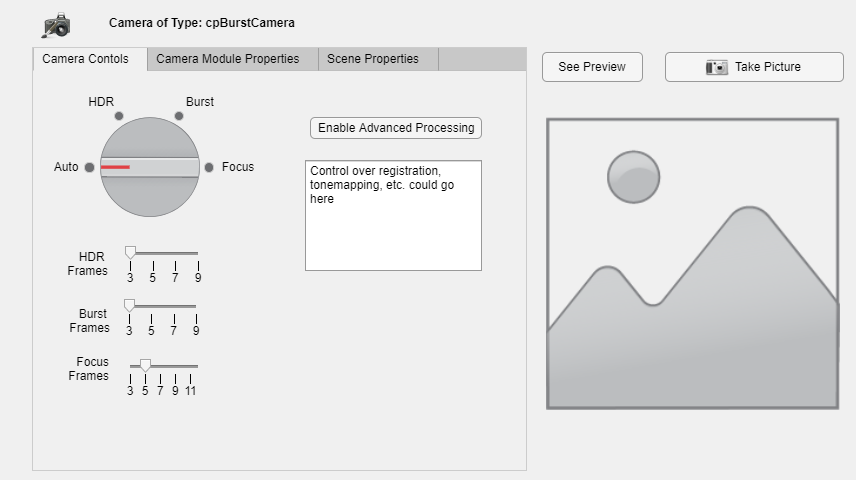

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 0.825460 seconds.
remote-render
default
pbrt version 4 (built Dec  2 2021 at 22:25:18)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.

Rendering: [                                           ] 
Rendering: [                                           ]  (0.1s|?s)  
Rendering: [                                           ]  (0.1s|?s)  
Rendering: [                                           ]  (0.2s|?s)  
Rendering: [                                           ]  (0.2s|?s)  
Rendering: [                                           ]  (0.3s|64.1s)  
Renderi

Error using piEXR2ISET (line 141)
Unknown optics type omni


Error in piRender (line 291)
    ieObject = piEXR2ISET(outFile, 'recipe',thisR,'label',thisR.metadata.rendertype);

Error in cpScene/render (line 339)
                            [sceneObje


stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 12, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');
cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');
cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 
disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));
disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));